# Numerical Definite Integration


$$\int_a^b{f\left( x \right) dx}$$


- integral function: $f\left( x \right)$

- upper limit: $b$

- lower limit: $a$

- number of splited intervals: $h,N;\,x_0,x_1,...,x_N;\,\,f_0,f_1,...,f_N
$

## function

mathematics definition: 

- see wiki: [https://en.wikipedia.org/wiki/Function_(mathematics)](https://en.wikipedia.org/wiki/Function_(mathematics))

- a process mapping element in set X to element in set Y

MATLAB: 

- function ret = function_name()

- hf1 = @(x) 3*x.^3

hf1 = @(x) 3*x.^3.*sin(x); %doc('@'); doc('function handle');
disp(hf1(1.2))

    4.8317


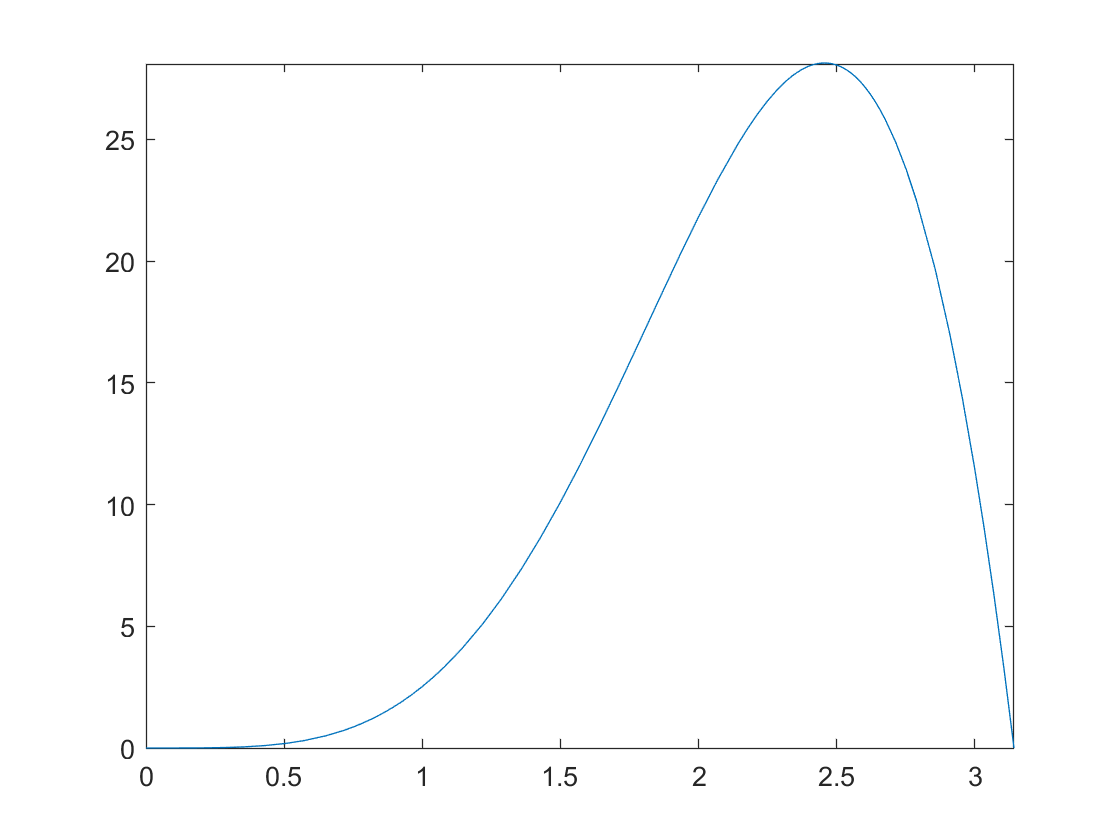

fplot(hf1, [0,pi]) %doc('fplot')

## paramter

hf1 = @(x) (3-x-x.^2).*sin(x).^2; %integral function; hf short for function handle
a = -1; %lower limit
b = 1; %upper limit

### plot integral area

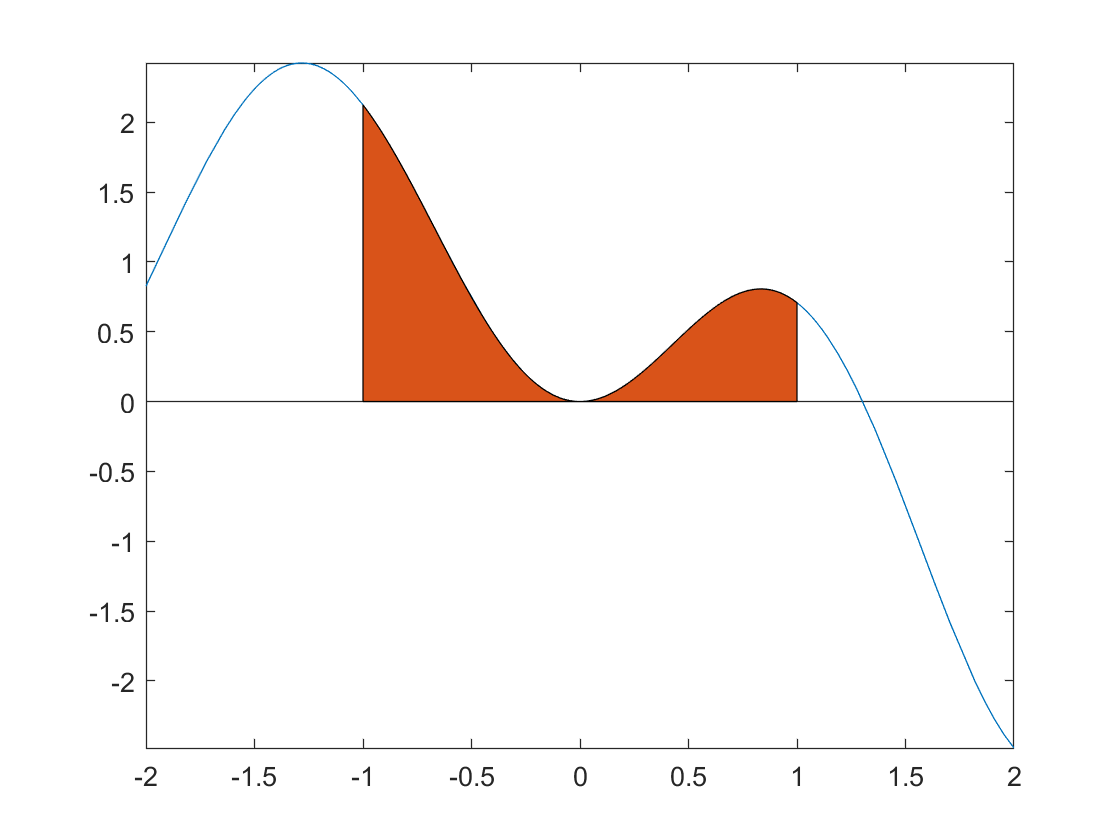

figure()
fplot(hf1, [a-1,b+1])
hold on;
area(linspace(a,b), hf1(linspace(a,b)))
hold off

## built-in (always check built-in first)

ret1 = integral(hf1, a, b); %doc('integral')
disp(['built-in integral: ', num2str(ret1,14)])

built-in integral: 1.321971464861


## rectangular rule

wiki - Riemann sum / Methods / Midpoint rule: [https://en.wikipedia.org/wiki/Riemann_sum](https://en.wikipedia.org/wiki/Riemann_sum)

error analysis (see lecture note): $\frac{f''\left( \xi \right) \left( b-a \right) ^3}{24N^2}$

ret1 = my_rectangular_integral(hf1, a, b, 500);
disp(['my_rectangular_integral: ', num2str(ret1,14)])

my_rectangular_integral: 1.3219709282588


## trapezoidal rule

wiki - trapezoidal rule: [https://en.wikipedia.org/wiki/Trapezoidal_rule](https://en.wikipedia.org/wiki/Trapezoidal_rule)

error analysis (see wiki): $\frac{f''\left( \xi \right) \left( b-a \right) ^3}{12N^2}$

ret1 = my_trapezoidal_integral(hf1, a, b, 500);
disp(['my_trapezoidal_integral: ', num2str(ret1,14)])

my_trapezoidal_integral: 1.3219725423669


## Simpsom's rule

wiki - Simpsom's rule: [https://en.wikipedia.org/wiki/Simpson%27s_rule](https://en.wikipedia.org/wiki/Simpson%27s_rule)

ret1 = my_simpsom_integral(hf1, a, b, 500);
disp(['my_simpsom_integral: ', num2str(ret1,14)])

my_simpsom_integral: 1.3210222221814


## Integral evaluation point

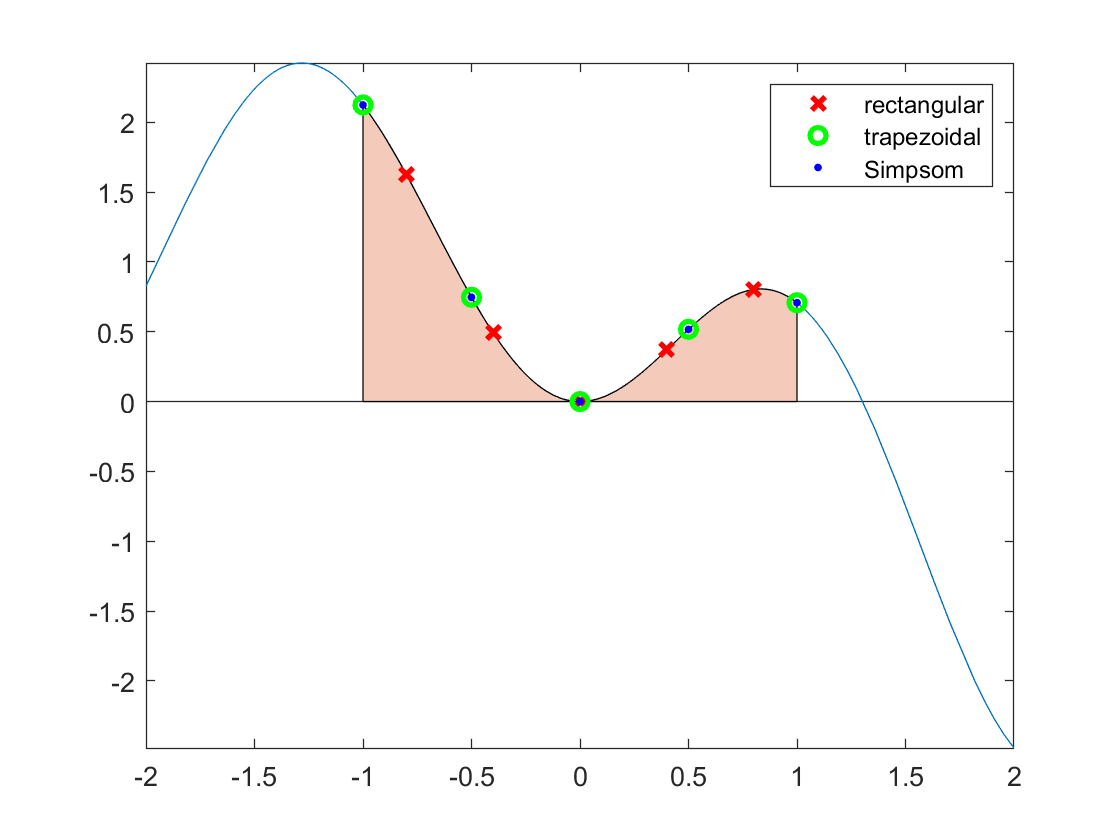

integral_evaluation_points(hf1, a, b)

weights

- rectangular rule: $$$
\text{1,1,...,}1
$$
$

- trapezoidal rule: $$$
\text{1,2,...,2,}1
$$
$

- Simpsom rule: $$$
\text{1,4,2,4,2,...,4,2,}1
$$
$

## Adaptive integral

reuse the evaluation value from last iteration

### Adaptive trapezoidal integral

ret1 = my_adaptive_trapezoidal_integral(hf1, a, b, 10);
disp(['my_adaptive_trapezoidal_integral: ', num2str(ret1,14)])

my_adaptive_trapezoidal_integral: 1.3219715288284


### Adaptive Simpsom integral

wiki: [https://en.wikipedia.org/wiki/Adaptive_Simpson%27s_method](https://en.wikipedia.org/wiki/Adaptive_Simpson%27s_method)

ret1 = my_adaptive_simpsom_integral(hf1, a, b, 10);
disp(['my_adaptive_simpsom_integral: ', num2str(ret1,14)])

my_adaptive_simpsom_integral: 1.3219714648609


## Monte Carlo's rule

wiki - Mote Carlo Integration: [https://en.wikipedia.org/wiki/Monte_Carlo_integration](https://en.wikipedia.org/wiki/Monte_Carlo_integration)

ret1 = my_MonteCarlo_rule(hf1, a, b, 5000); % 5000 is number of random generated point
disp(['my_MonteCarlo_rule: ', num2str(ret1,14)])

my_MonteCarlo_rule: 1.3331191253745


## function

function ret = my_rectangular_integral(hf1, a, b, num_point)
tmp1 = linspace(a,b,num_point+1);
x = (tmp1(1:(end-1))+tmp1(2:end))/2;
ret = sum(hf1(x))*(b-a)/num_point;
end

function ret = my_trapezoidal_integral(hf1, a, b, num_point)
x = linspace(a,b,num_point);
ret = (hf1(x(1))/2 + hf1(x(end))/2 + sum(hf1(x(2:(end-1)))))* (b-a)/(num_point-1);
end

function ret = my_simpsom_integral(hf1, a, b, num_point)
x = linspace(a,b,num_point);
weight = ones(1,num_point);
weight(3:2:end-1) = 2;
weight(2:2:end-1) = 4;
weight = weight*(b-a)/(num_point-1)/3;
ret = sum(hf1(x).*weight);
end

function ret = my_MonteCarlo_rule(hf1, a, b, num_point)
x = rand([1,num_point])*(b-a) + a;
ret = sum(hf1(x))/num_point * (b-a);
end

function integral_evaluation_points(hf1, a, b)
fig = figure();
ax = axes(fig);
fplot(ax, hf1, [a-1,b+1]) %doc('fplot')
ax.NextPlot = 'add';
area(ax, linspace(a,b), hf1(linspace(a,b)), 'FaceAlpha', 0.3)

% rectangular rule
num_point = 5;
tmp1 = linspace(a,b,num_point+1);
x = (tmp1(1:(end-1))+tmp1(2:end))/2;
hline1 = line(x, hf1(x), 'Marker', 'x', 'MarkerSize', 7, 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2);
% trapezoidal rule
num_point = 5;
x = linspace(a,b,num_point);
hline2 = line(x, hf1(x), 'Marker', 'o', 'LineStyle', 'none', 'Color', 'g', 'LineWidth', 2);
% Simpsom rule (save as trapezoidal rule)
num_point = 5;
x = linspace(a,b,num_point);
hline3 = line(x, hf1(x), 'Marker', '.', 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 2, 'MarkerSize', 10);
legend([hline1,hline2,hline3], {'rectangular', 'trapezoidal','Simpsom'})
end

function ret = my_adaptive_trapezoidal_integral(hf1, a, b, num_iter)
sum_d = hf1(a) + hf1(b);
sum_o = hf1((a+b)/2);
sum_e = 0;
for ind1 = 1:num_iter
    sum_e = sum_o + sum_e;
    tmp1 = (b-a)/2^ind1;
    sum_o = sum(hf1(a+tmp1/2 + tmp1*(0:(2^ind1-1))));
end
ret = (b-a)/2^(num_iter+1)/2*(sum_d + 2*sum_e + 2*sum_o);
end

function ret = my_adaptive_simpsom_integral(hf1, a, b, num_iter)
sum_d = hf1(a) + hf1(b);
sum_o = hf1((a+b)/2);
sum_e = 0;
for ind1 = 1:num_iter
    sum_e = sum_o+sum_e;
    tmp1 = (b-a)/2^ind1;
    sum_o = sum(hf1(a+tmp1/2 + tmp1*(0:(2^ind1-1))));
end
ret = (b-a)/2^(num_iter+1)/3*(sum_d + 2*sum_e + 4*sum_o);
end
